#### Calculation of Ti

% Gegebene Parameter
Tm = 1000e-3; % in Sekunden
omega_D = pi / Tm;
Tt = 0.1;
T = 0.316; 
phi_Res_deg = 65; % Phasenreserve in Grad
phi_Res_rad = deg2rad(phi_Res_deg); % Phasenreserve in Radian

% Funktion für die Gesamtphase 
G0_phase = @(Ti) -atan(omega_D * T) - omega_D * Tt - atan(1 / (omega_D * Ti));

% Lösen der Gleichung für Ti
Ti = fzero(@(Ti) G0_phase(Ti) + pi - phi_Res_rad, 1); % Startwert ist 1

% Ausgabe des Ergebnisses
fprintf('Der berechnete Wert für Ti ist: %f Sekunden\n', Ti);

Der berechnete Wert für Ti ist: 0.246830 Sekunden


#### Calculation of kr

ku = 2.51; % Verstärkung 
Tm = 1000e-3;
omega_D = pi / Tm; % Durchtrittsfrequenz % in Sekunden

% Berechnung von kr
kr = (sqrt(1 + (omega_D * T)^2)) / (ku * sqrt(1 + (1 / (-omega_D * T))^2));

% Ausgabe des Ergebnisses
fprintf('Der berechnete Wert für kr ist: %f\n', kr);

Der berechnete Wert für kr ist: 0.344014


#### b) Check results with margin()

% Definition der Übertragungsfunktion des Reglers GR(s)
s = tf('s');
GR = kr * (1 + (1/(Ti * s)));
GS = (ku * exp((-s * Tt))) / (1 + T * s);

% Offene Schleifenübertragungsfunktion G0(s)
G0 = GR * GS;
[gainMargin, phaseMargin, gainCrossOverFrequency, phaseCrossOverFrequency] = margin(G0);

fprintf('Phasenreserve: %f Grad\n', phaseMargin);

Phasenreserve: 93.902613 Grad


fprintf('Amplitudenreserve: %f Grad\n', gainMargin);

Amplitudenreserve: 6.110208 Grad


fprintf('Kontrolle: Phasendurchtrittsfrequenz: %f rad/s\n', phaseCrossOverFrequency);

Kontrolle: Phasendurchtrittsfrequenz: 1.971778 rad/s


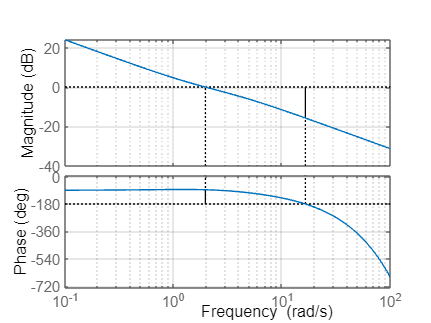


% Erstellung des Bode-Plots mit markierten Margins
figure;
margin(G0);
grid on;

#### c) step()

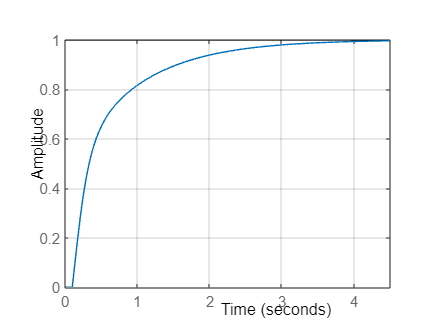

% Übertragungsfunktion des geschlossenen Regelkreises Gw(s)
Gw = feedback(G0, 1);

% Plotten der Sprungantwort
figure;
step(Gw);
grid on;


% Berechnung des Überschwingens und der Überschwingzeit
S = stepinfo(Gw);

fprintf('Überschwingen:   %f \n', S.Overshoot);

Überschwingen:   0.000000 


fprintf('Überschwingzeit: %f s\n', S.SettlingTime);

Überschwingzeit: 3.035945 s


#### d) Discrete-time Control

TA = 0.02;  % Abtastzeit

tf_P = kr;

num_I = [kr];
denum_I = [Ti 0];

tf_I_cont = tf(num_I, denum_I)

tf_I_cont =
 
   0.344
  --------
  0.5463 s
 
Continuous-time transfer function.
Model Properties


tf_I_dis = c2d(tf_I_cont, TA, 'tustin')

tf_I_dis =
 
  0.006298 z + 0.006298
  ---------------------
          z - 1
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties
